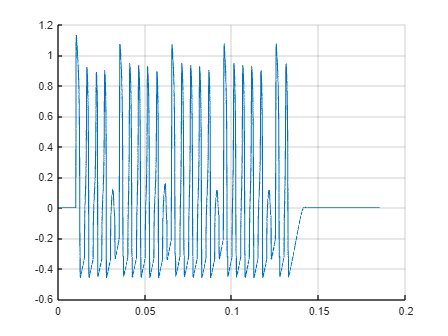

warning ('off','all');

params.Tau = 2000.00;
params.TauR = 2000.00;
params.gc = 4.00;
params.NaX = 0.50;
params.alpha = 10;
params.b = 1;

% Soma parameters
paramsSoma = params;
paramsSoma.NaX = 1; % Always 1

% Initial conditions
initCon = [0.00; 0.00];

soma = Dendrite(0, paramsSoma, initCon);
dendrite = Dendrite(0, params, initCon);

% dendritic tree model
tree = DendriteTreeModel();

% Add soma
tree.addDendrite(soma);

dend = false;

if dend
    %Add dendrites
    for i=1:1
        dendrite.ID = i;
        tree.addDendrite(dendrite);
    end

    %Define connections
    tree.addConnectionStr("0-1");
end

fs = 64e+3;
h = 1/fs;
tmax = 1;
% A, F
[t, sig] = supraStep(2, 2e+2, fs, 25, "type","step", "numZeroPeriodsStart",2,"numZeroPeriodsEnd", 10);
%[t, sig, ~] = Chirp(1, tmax, fs, 50, 1000, "signal","square", "type","linear");
tree.verify();

if dend
    tree.addStimuli(1, sig);
else
    tree.addStimuli(0, sig);
end

[t, sol] = treeSolver(tree, max(t), h);
%[t, sol] = treeSolver(tree, tmax, h);

figure
hold on
plot(t, sol(1, :), LineWidth=1)
%plot(t, sig, "--", LineWidth=0.5)
grid on


consts.MIN_SWA = 5; % mV
consts.DELAY_FACTOR = 2;
consts.TSTUT_PRE_FACTOR = 2.5;
consts.TSTUT_POST_FACTOR = 1.5;
consts.PSTUT_FACTOR = 1.5;
consts.SLN_FACTOR = 2;
consts.SLOPE_THRESHOLD = 0.003;
consts.MIN_TSTUT_FREQ = 25; % Hz

classifyFiringPattern(sol(1, :), fs, 0.8, consts)

ans = 'NASP/STEADY_STATE.'